# Actividad Final

### Eleazar Olivas Gaspar A01731405

Para la actividad final del modulo se pide entregar un simulacion para los siguientes problomas lo cuales se irán resolviendo en conjunto con su simulacion 1 a 1.

#### Problema 1:

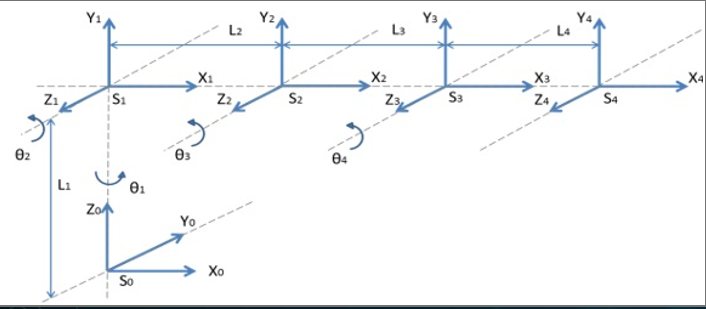

Figura 1: problema de simulación 1.

A continuacion se muestra el codígo para la simulacion del primer problema.

%Eleazar Olivas Garpar
%A01731405
%Activdad 1.12 Ejercicio 1

%Limpieza de pantalla
clear all
close all
clc
l1 = 1; l2 = 1; l3 = 1; l4 = 1;
%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2),  [0 0 l1]);
H2=SE3([l2 0 0]);
H3=SE3([l3 0 0]);
H4=SE3([l4 0 0]);

H20= H1*H2;
H30= H20*H3;
H40= H30*H4;%Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3 ];
y=[0 0 0 0 0 ];
z=[0 1 1 1 1 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30);

    1         0         0         2
    0         0        -1         0
    0         1         0         1
    0         0         0         1


 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H40);

    1         0         0         3
    0         0        -1         0
    0         1         0         1
    0         0         0         1


Como se puede obserbar se obtuvo de forma correcta la simulación y al final de esta de muestra la matris de  transformacion del efector final.

#### Problema 2:

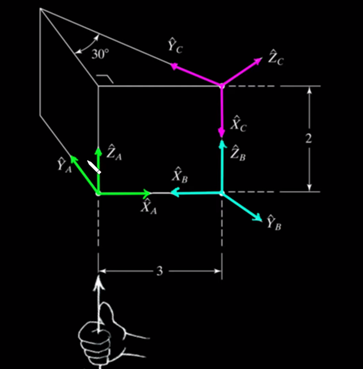

Figura 2: problema de simulación 2.

%Eleazar Olivas Garpar
%A01731405
%Activdad 1.12 Ejercicio 2

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0])

 

H3 = 
         1         0         0        -2
         0   -0.8660   -0.5000         0
         0    0.5000   -0.8660         0
         0         0         0         1



H20= H1*H2;
H30= H20*H3 %Matriz de transformación homogenea global de 3 a 0 

 

H30 = 
         0   -0.5000    0.8660         3
         0    0.8660    0.5000         0
        -1         0         0         2
         0         0         0         1



%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30);

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1


#### Problema 3:

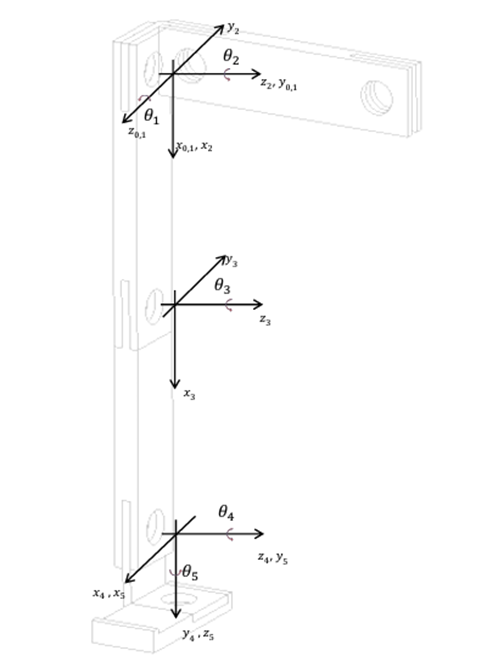

Figura 3: problema de simulación 3.

%Eleazar Olivas Garpar
%A01731405
%Activdad 1.12 Ejercicio 3
%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3(roty(pi/2), [0 0 0]);
H1=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(roty(0), [2 0 0]);
H3=SE3(rotz(-pi/2), [2 0 0]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;

%Coordenadas de la estructura de translación y rotación
x=[0 2 4];
y=[0 0 0];
z=[0 0 0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])

  disp(H30);

    0         1         0         4
    0         0         1         0
    1         0         0         0
    0         0         0         1


  disp(H3);

     0         1         0         2
    -1         0         0         0
     0         0         1         0
     0         0         0         1


#### Problema 4:

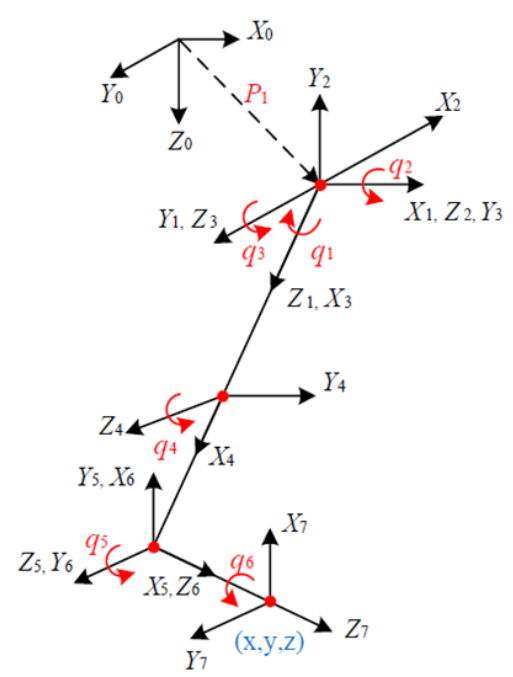

%Eleazar Olivas Garpar
%A01731405
%Activdad 1.12 Ejercicio 4
%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3(rotx(pi), [0 0 0]);
H1=SE3(rotz(pi/2), [0 0 0]);
H2=SE3(rotx(pi/2), [0 0 0]);
H3=SE3(rotz(-pi/2), [0 0 0]);
H4=SE3(rotx(pi/2), [0 0 0]);
H5=SE3(rotz(0), [3 0 0]);
H6=SE3(rotz(pi/2), [3 0 0]);
H7=SE3(rotz(pi/2), [0 0 0]);
H8=SE3(rotx(pi/2), [0 0 0]);
H9=SE3(rotz(0), [0 0 3]);

%Matriz de transformación homogenea global de 3 a 0 
H20=H1*H2;
H30= H20*H3;
H40=H30*H4;
H50=H40*H5;
H60=H50*H6;
H70=H60*H7;
H80=H70*H8;
H90=H80*H9;

%Coordenadas de la estructura de translación y rotación
x=[0 0 0 3];
y=[0 0 0 0];
z=[0 -3 -6 -6];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 6 -1 6 -1 6]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 6 -1 6 -1 6])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 6 -1 6 -1 6])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 6 -1 6 -1 6])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H40, H50,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H50, H60,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H60, H70,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H70, H80,'rgb','axis', [-1 6 -1 6 -1 6])
  % % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H80, H90,'rgb','axis', [-1 6 -1 6 -1 6])

  disp(H90);

    0         0         1         3
    0        -1         0         0
    1         0         0        -6
    0         0         0         1


  disp(H9);

    1         0         0         0
    0         1         0         0
    0         0         1         3
    0         0         0         1


#### Problema 5 (Cinemática problema 4):

% Limpieza de pantalla
clear all
close all
clc

% Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t l1 l2 l3

% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [0 0 0];

% Creamos el vector de coordenadas articulares
Q = [th1, th2, th3];

% Creamos el vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad del robot
GDL = length(RP);

% Matrices de rotación para cada articulación
rotacion_x = @(theta) [1 0 0; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
rotacion_y = @(theta) [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
rotacion_z = @(theta) [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1];

% Inicialización de matrices de transformación homogénea
T = sym(eye(4));  % T inicializada como matriz identidad
R = sym(zeros(3, 3, GDL));
P = sym(zeros(3, 1, GDL));

% Articulación 1 
R(:,:,1) = rotacion_z(-th1(t)) * rotacion_x(th2) * rotacion_x(th3) * rotacion_x(-pi/2) * rotacion_z(-pi/2);
P(:,:,1) = [0; 0; l1];
T(:,:,1) = [R(:,:,1) P(:,:,1); 0 0 0 1];

% Articulación 2
R(:,:,2) = rotacion_z(th4(t));
P(:,:,2) = [l2; 0; 0];
T(:,:,2) = T(:,:,1) * [R(:,:,2) P(:,:,2); 0 0 0 1];

% Articulación 3 
R(:,:,3) = rotacion_z(th5(t)) * rotacion_z(pi) * rotacion_x(pi/2);
P(:,:,3) = [0; 0; l3];
T(:,:,3) = T(:,:,2) * [R(:,:,3) P(:,:,3); 0 0 0 1];

% Articulación 4
R(:,:,3) = rotacion_z(th6(t));
P(:,:,3) = [0; 0; 0];
T(:,:,3) = T(:,:,2) * [R(:,:,3) P(:,:,3); 0 0 0 1];

% Matriz de transformación global
T_global = simplify(T(:,:,3));

% Jacobianos
Jv_a = sym(zeros(3, GDL));
Jw_a = sym(zeros(3, GDL));

for k = 1:GDL
    if RP(k) == 0
        % Para las juntas de revolución
        if k == 1
            z_prev = [0; 0; 1];
            p_prev = [0; 0; 0];
        else
            z_prev = T(1:3, 3, k-1);
            p_prev = T(1:3, 4, k-1);
        end
        Jv_a(:,k) = simplify(cross(z_prev, T(1:3, 4, GDL) - p_prev));
        Jw_a(:,k) = z_prev;
    else
        % Para las juntas prismáticas
        if k == 1
            Jv_a(:,k) = [0; 0; 1];
        else
            Jv_a(:,k) = T(1:3, 3, k-1);
        end
        Jw_a(:,k) = [0; 0; 0];
    end
end

%Jv_a = simplify(Jv_a);
%Jw_a = simplify(Jw_a);

% Velocidad lineal y angular
%V = simplify(Jv_a * transpose(Qp));
%W = simplify(Jw_a * transpose(Qp));

% Resultados
disp('Matriz de Transformación global T');

Matriz de Transformación global T


%pretty(T_global);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


Jv_a = simplify(Jv_a)

%pretty(Jv_a);
disp('Jacobiano angular obtenido de forma analítica');

Jacobiano angular obtenido de forma analítica


Jw_a = simplify(Jw_a)

$$Jw\_a = \begin{array}{l} \left(\begin{array}{ccc} 0 & \sigma_{2} & \sigma_{2}\\ 0 & \sigma_{1} & \sigma_{1}\\ 1 & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)-\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sigma_{2}=\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right) \end{array}$$

%pretty(Jw_a);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V = simplify(Jv_a * transpose(Qp))

%pretty(V);
disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W = simplify(Jw_a * transpose(Qp))

$$W(t) = \begin{array}{l} \left(\begin{array}{c} \left(\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)+\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\right)\,\sigma_{1}\\ -\left(\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)-\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\right)\,\sigma_{1}\\ \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)+\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)+\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)+\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right) \end{array}$$

%pretty(W);
